clc, clear all
close all
syms t r
d = 0.235

d = 0.2350

alpha = 0.25;
ri=1.584*cos(2.65*alpha*t+3.71);
rj=-3.96*sin(alpha*t+1.4);
rk=0*alpha*t;
r=[ri,rj,rk];
dr=diff(r,t);
T_hat_ugly=dr./norm(dr);
assume(t,'real') % parameter u should be real


% Unit Tangent
T_hat=simplify(T_hat_ugly)

$$T\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{53\,\sin\left(\frac{53\,t}{80}+\frac{371}{100}\right)}{\sigma_{1}} & -\frac{50\,\cos\left(\frac{t}{4}+\frac{7}{5}\right)}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2500\,{\cos\left(\frac{t}{4}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,t}{80}+\frac{371}{100}\right)}^{2}} \end{array}$$

dT_hat=diff(T_hat,t);

% Unit Normal
N_hat_ugly=dT_hat/norm(dT_hat);
N_hat=simplify(N_hat_ugly)

$$N\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{2\,\left(483625\,\sigma_{6}+702250\,\sigma_{5}+218625\,\sigma_{4}\right)}{\sigma_{1}} & \frac{561800\,\sin\left(\frac{t}{4}+\frac{7}{5}\right)+1025285\,\sigma_{3}+463485\,\sigma_{2}}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=265\,\sqrt{2500\,{\left(73\,\sigma_{6}+106\,\sigma_{5}+33\,\sigma_{4}\right)}^{2}+2809\,{\left(40\,\sin\left(\frac{t}{4}+\frac{7}{5}\right)+73\,\sigma_{3}+33\,\sigma_{2}\right)}^{2}}\\ \sigma_{2}=\sin\left(\frac{63\,t}{40}+\frac{441}{50}\right)\\ \sigma_{3}=\sin\left(\frac{43\,t}{40}+\frac{301}{50}\right)\\ \sigma_{4}=\cos\left(\frac{93\,t}{80}+\frac{651}{100}\right)\\ \sigma_{5}=\cos\left(\frac{53\,t}{80}+\frac{371}{100}\right)\\ \sigma_{6}=\cos\left(\frac{13\,t}{80}+\frac{91}{100}\right) \end{array}$$


% Import Stuff
velocity_dataset = readmatrix('Velocity_Data_2.csv');

% Put imported data into matrices
Time = velocity_dataset(:,1);
Left_Position = velocity_dataset(:,2);
Right_Position = velocity_dataset(:,3);

% Find dr for measured data
dr_measured = [diff(Left_Position)./diff(Time), ...
               diff(Right_Position)./diff(Time), ...
               zeros(284,1)];

% Find theoretical angular velocity function
Angular_Velocity_ugly = cross(T_hat,dT_hat);
Angular_Velocity = simplify(Angular_Velocity_ugly)

$$Angular\_Velocity = \left(\begin{array}{ccc} 0 & 0 & -\frac{19345\,\cos\left(\frac{33\,t}{80}+\frac{231}{100}\right)+8745\,\cos\left(\frac{73\,t}{80}+\frac{511}{100}\right)}{20000\,\cos\left(\frac{t}{2}+\frac{14}{5}\right)-22472\,\cos\left(\frac{53\,t}{40}+\frac{371}{50}\right)+42472} \end{array}\right)$$

% Calculate linear speed theoretical
Linear_Speed = simplify(abs(dr))

$$Linear\_Speed = \left(\begin{array}{ccc} \frac{5247\,\left|\sin\left(\frac{53\,t}{80}+\frac{371}{100}\right)\right|}{5000} & \frac{99\,\left|\cos\left(\frac{t}{4}+\frac{7}{5}\right)\right|}{100} & 0 \end{array}\right)$$

% Calculate linear speed measured
Linear_Speed_measured = abs(dr_measured);
Linear_Speed_measured_norm = sqrt(Linear_Speed_measured(:,1).^2 + ...
                                  Linear_Speed_measured(:,2).^2);
Linear_Speed_Measured_2 = (dr_measured(:,1)+dr_measured(:,2))./2

Linear_Speed_Measured_2 =    -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


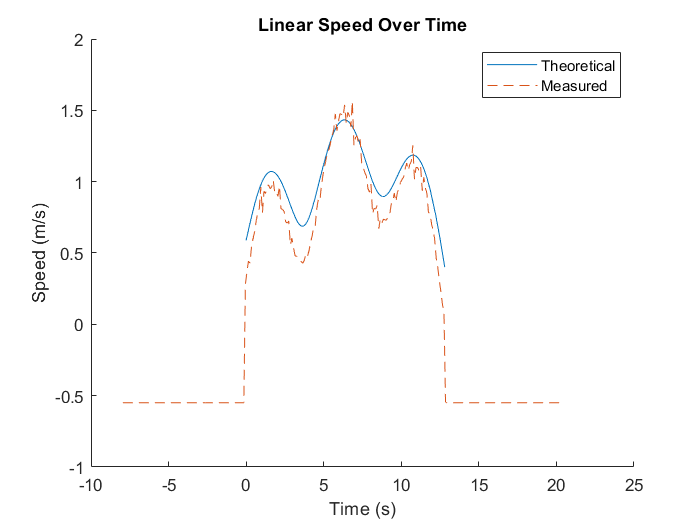

% Plot linear speed
phase_shift = 142.25;
upward_shift = 0.55;
figure(1)
clf;
hold on;
fplot(norm(Linear_Speed),[0,3.2/alpha])
plot(Time(2:end)-phase_shift, ...
     Linear_Speed_measured_norm-upward_shift,'--')
legend('Theoretical','Measured')
title('Linear Speed Over Time')
xlabel('Time (s)')
ylabel('Speed (m/s)')
hold off;

% Plot Angular Velocity
d = 0.235

d = 0.2350

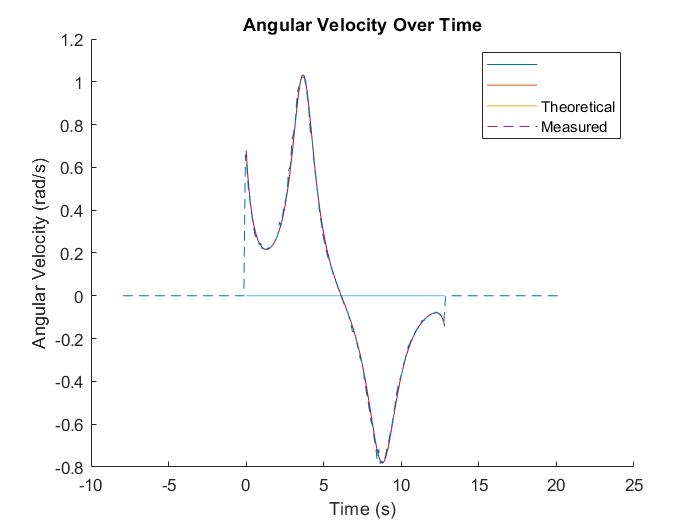

Angular_Velocity_measured = (diff(Right_Position)./diff(Time)-diff(Left_Position)./diff(Time))./d;
clf;
figure(2)
hold on;
fplot(Angular_Velocity,[0,3.2/alpha])
plot(Time(2:end,:)-phase_shift,Angular_Velocity_measured,'--')
title('Angular Velocity Over Time')
legend('','','Theoretical','Measured')
xlabel('Time (s)')
ylabel('Angular Velocity (rad/s)')
hold off;

% Calculate Wheel Velocities theoretical
Wheel_Left_ugly = norm(dr) - Angular_Velocity_ugly(3).*(d/2);
Wheel_Left = simplify(Wheel_Left_ugly)

$$Wheel\_Left = \begin{array}{l} \frac{181843\,\cos\left(\frac{33\,t}{80}+\frac{231}{100}\right)+82203\,\cos\left(\frac{73\,t}{80}+\frac{511}{100}\right)+31680\,\cos\left(\frac{t}{2}+\frac{14}{5}\right)\,\sigma_{1}-\frac{4449456\,\sigma_{2}\,\sigma_{1}}{125}+\frac{8409456\,\sigma_{1}}{125}}{640\,\left(2500\,\cos\left(\frac{t}{2}+\frac{14}{5}\right)-2809\,\sigma_{2}+5309\right)}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2500\,{\cos\left(\frac{t}{4}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,t}{80}+\frac{371}{100}\right)}^{2}}\\ \sigma_{2}=\cos\left(\frac{53\,t}{40}+\frac{371}{50}\right) \end{array}$$

Wheel_Right_ugly = norm(dr) + Angular_Velocity_ugly(3).*(d/2);
Wheel_Right = simplify(Wheel_Right_ugly)

$$Wheel\_Right = \begin{array}{l} -\frac{181843\,\cos\left(\frac{33\,t}{80}+\frac{231}{100}\right)+82203\,\cos\left(\frac{73\,t}{80}+\frac{511}{100}\right)-31680\,\cos\left(\frac{t}{2}+\frac{14}{5}\right)\,\sigma_{1}+\frac{4449456\,\sigma_{2}\,\sigma_{1}}{125}-\frac{8409456\,\sigma_{1}}{125}}{640\,\left(2500\,\cos\left(\frac{t}{2}+\frac{14}{5}\right)-2809\,\sigma_{2}+5309\right)}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2500\,{\cos\left(\frac{t}{4}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,t}{80}+\frac{371}{100}\right)}^{2}}\\ \sigma_{2}=\cos\left(\frac{53\,t}{40}+\frac{371}{50}\right) \end{array}$$

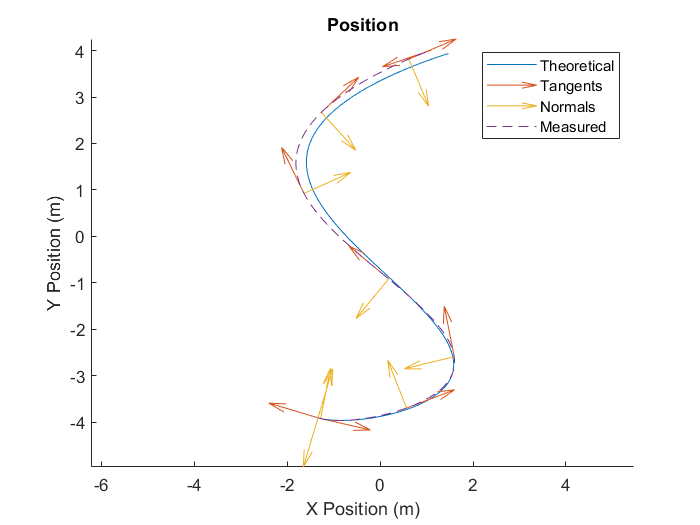


% Create arrays for measured plot
array_x = zeros(284,1);
array_y = zeros(284,1);
array_theta = zeros(284,1);
Initial_Angle_Temp = double(subs(T_hat,t,0));
array_theta(1) = atan(Initial_Angle_Temp(:,2)/Initial_Angle_Temp(:,1));
array_x(1) = double(subs(ri,t,0));
array_y(1) = double(subs(rj,t,0));

% calculate measured array values
time_shortened = diff(Time(2:end));
for i = 1:283
    array_x(i+1) = array_x(i) + Linear_Speed_Measured_2(i)*...
                                cos(array_theta(i))*time_shortened(i);
    array_y(i+1) = array_y(i) + Linear_Speed_Measured_2(i)*...
                                sin(array_theta(i))*time_shortened(i);
    array_theta(i+1) = array_theta(i) + Angular_Velocity_measured(i)*time_shortened(i);
end

% create unit tangent values for quiver
array_v = [diff(array_x)./diff(Time(2:end)),diff(array_y)./diff(Time(2:end))];
array_t = array_v./(sqrt(array_v(:,1).^2+array_v(:,2).^2));
t_x = array_t(:,1);
t_y = array_t(:,2);

% create unit normal values for quiver
array_t_prime = diff(array_t)./diff(Time(3:end));
array_n = array_t_prime./(sqrt(array_t_prime(:,1).^2+array_t_prime(:,2).^2));
n_x = array_n(:,1);
n_y = array_n(:,2);

% Plot position
skip_length = 20;
figure(3)
clf;
hold on;
fplot(ri,rj,[0,3.2/alpha])
quiver(array_x(1:skip_length:end),array_y(1:skip_length:end),...
               t_x(1:skip_length:end),t_y(1:skip_length:end),0.5)
quiver(array_x(1:skip_length:end),array_y(1:skip_length:end),...
               n_x(1:skip_length:end),n_y(1:skip_length:end),0.5)
plot(array_x,array_y,'--')
legend('Theoretical','Tangents','Normals','Measured')
axis equal
title('Position')
xlabel('X Position (m)')
ylabel('Y Position (m)')
hold off;

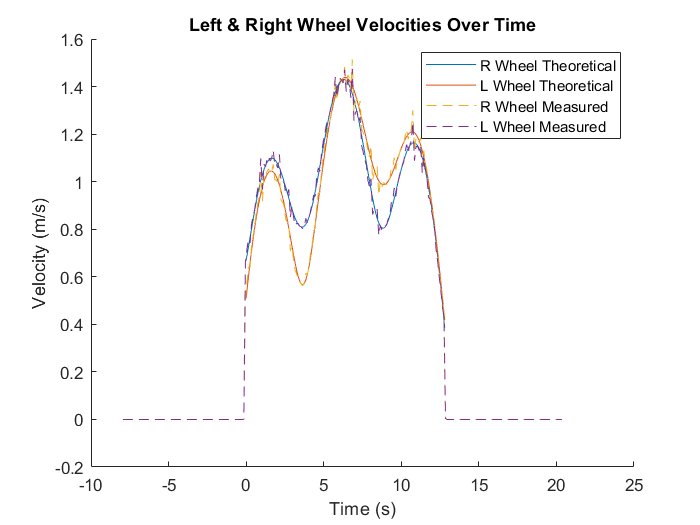

% Right & Left Wheel Velocities Over Time
figure(4)
clf;
hold on;
fplot(Wheel_Right,[0,3.2/alpha])
fplot(Wheel_Left,[0,3.2/alpha])
plot(Time(2:end)-phase_shift,diff(Left_Position)./diff(Time),'--')
plot(Time(2:end)-phase_shift,diff(Right_Position)./diff(Time),'--')
legend('R Wheel Theoretical','L Wheel Theoretical', ...
       'R Wheel Measured', 'L Wheel Measured')
title('Left & Right Wheel Velocities Over Time')
xlabel('Time (s)')
ylabel('Velocity (m/s)')
hold off;